### **Problem 2**

time  = [0 6 12 18 24 30 36 42 48 54 60 66 72 78 84];
speed = [124 134 148 156 147 133 121 109 99 85 78 89 104 116 123];
h = time(2) - time(1);
N = length(speed);

To find the length of the track we require the following integral:


$$\int_0^{84} |f^{\prime } \left(x\right)|\;\textrm{dx}$$


where $f^{\prime } \left(x\right)$is the function that outputs the rate of change (speed) at some time$x$.

However given that on the interval [0, 84],  we can drop the abs value. 

#### **Composite Trapezoidal rule**

CTRAP_r_sum = 0;
for i = 2: N - 1
    CTRAP_r_sum = CTRAP_r_sum + 2.*speed(i);
end

CTRAP_r_sum = (h./2)*(CTRAP_r_sum + speed(1) + speed(N))

CTRAP_r_sum =         9855


#### **Composite Simpson’s rule**

h = 6;

XI0 = speed(1) + speed(N);
XI1 = 0;
XI2 = 0;

for i = 2: N - 1
    
    if(mod(i, 2) == 0)
        XI2 = XI2 + speed(i);
    else
        XI1 = XI1 + speed(i);
    end

end

CSIMP_r_sum = h*(XI0 + 2.*XI1 + 4.*XI2)./3

CSIMP_r_sum =         9858


#### **Comparison**

Lets plot the points to get an idea about the concavity of the function. 

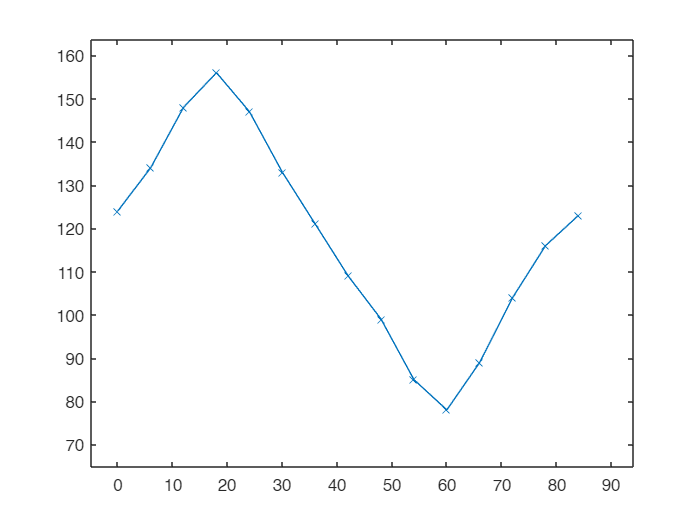

plot(time, speed, "-x");

Unfortunately, the function does not contain many curves. Thus we cannot make an argument for any approxmiations overshooting/undershooting the actual area under the curve. However it does seem that the Composite Simpson’s rule does count three more units of area. 

Given that h=6, it may be the case that Composite Simpson’s rule may be less accurate due to its higher order error term. If $h<1$, it would not have been the case. 